# On-Board Charger (OBC) for Electric Vehicles

## **Before you get started**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternatively, select **Hide Code **using the icon   at the top right of the Live Editor pane.

Some interactions require basic MATLAB familiarity. If you need a refresher, MATLAB Onramp is a free, two-hour tutorial that covers the essentials.[](https://www.mathworks.com/learn/tutorials/matlab-onramp.html)

Work through the sections in order. Some sections use variables created earlier, so running sections out of sequence may produce errors.

## 1. Introduction

An on-board charger (OBC) charges an electric vehicle (EV) directly from the power grid. Because the charger is carried in the vehicle, its size, weight, and efficiency directly affect vehicle range, energy use, and charging cost.

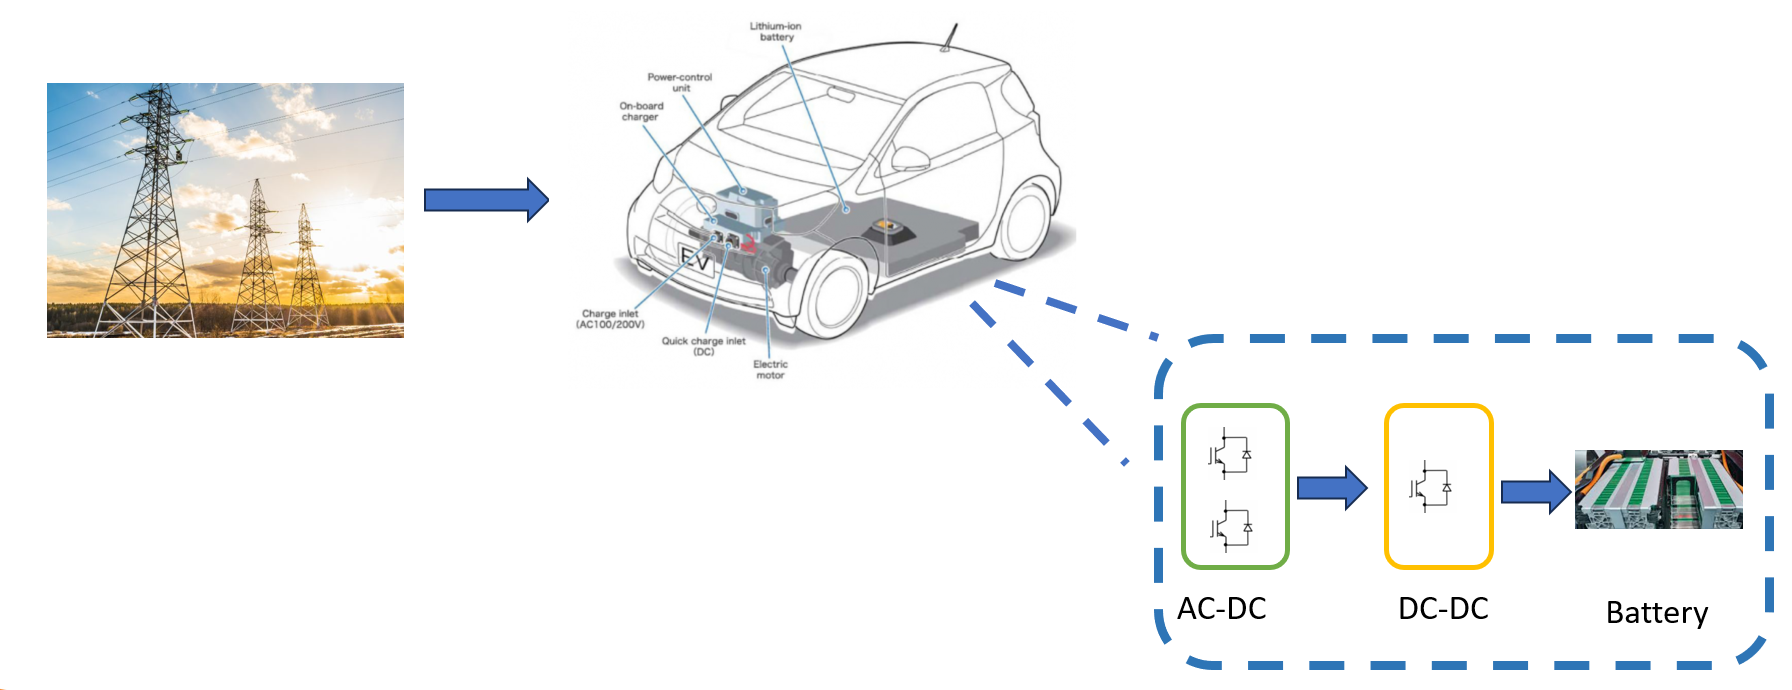

The structure of the on-board charger system 

A high-performance on-board charger should satisfy four requirements:

- The OBC must control the battery charging current and/or voltage.

- The OBC must maintain unity power factor while charging the battery (Iq = 0).

- For safety, the OBC should be isolated from the grid.

- The OBC should be small and light.

By the end of this activity, you should be able to explain how an on-board charger manages battery current, battery voltage, power factor, and grid isolation during charging.

## 2. Charging the battery

Battery charging must balance speed, safety, and battery life. Most charging profiles use two stages: constant-current charging and constant-voltage charging.

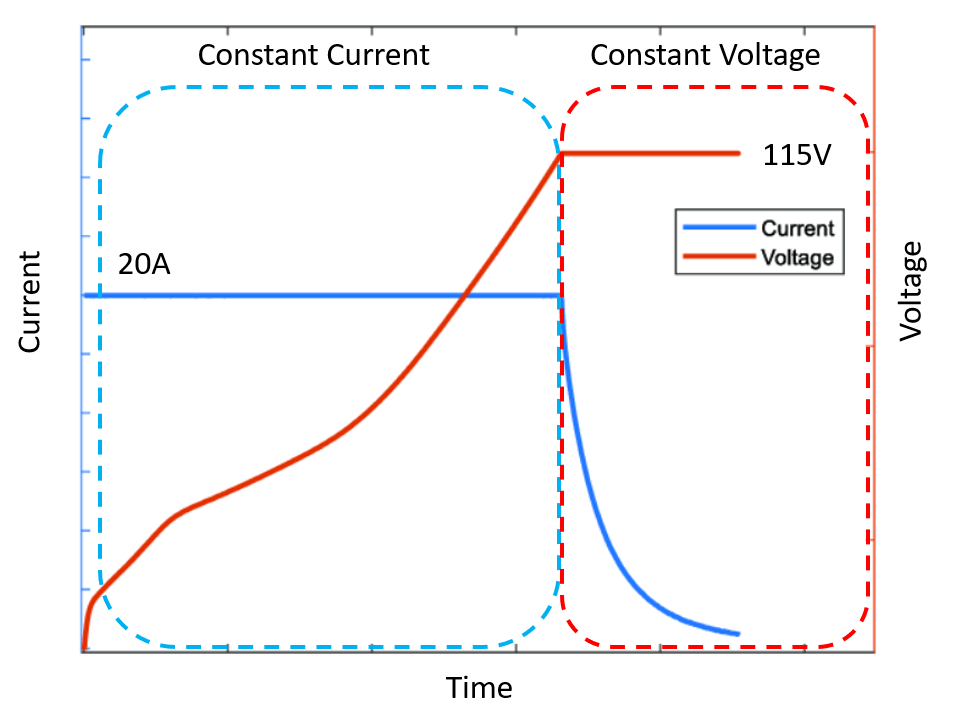

State of charge (SOC) measures the battery charge as a percentage of full charge. In this model, SOC helps you identify where the charging process transitions between stages. SOC is calculated as shown below:


$$\mathrm{SOC}=100\left(1-\frac{1}{Q}\int_0^t i\left(t\right)dt\right)$$


## 3. Circuit

## 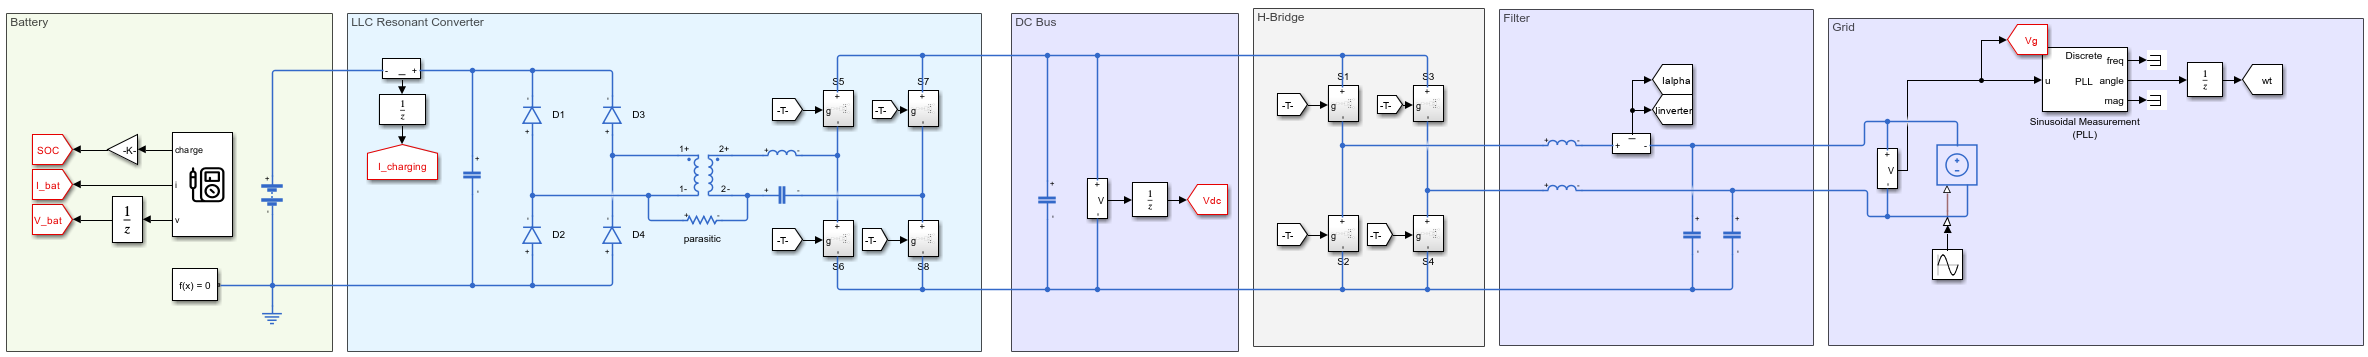

Click the button below to open and explore the model. 

 
open_system("Models/onboard_SSC_simscape.slx")
if ~exist('Vbat_ref','var')
    Vbat_ref = 115;  
end

Before running, predict how battery voltage, battery current, and battery power should change during charging. After the simulation is complete (this may take a few minutes), use the following plots to evaluate your prediction:

- DC output voltage

- Inverter current

- Battery voltage and current

- Battery power

 
disp("Please wait for the simulation to finish. This may take a few minutes")
runmodel_onboard();
disp("Simulation completed. You can now analyze the results")

Use the menu below to focus on each section of the model and connect it to the plotted responses.

switchRectifier("No Selection");

### 3.1 Connect to the Grid

For this simulation, the inverter output must match the grid frequency and phase angle. A phase-locked loop (PLL) estimates the grid phase and frequency. You do not need to analyze the PLL internals here; focus on how synchronization supports grid connection.

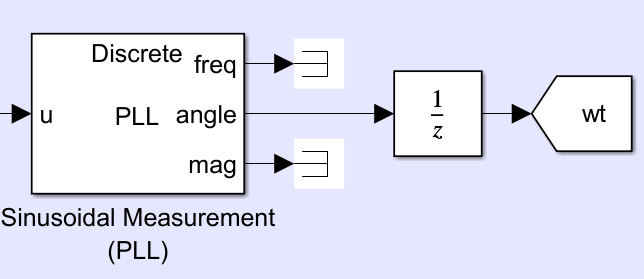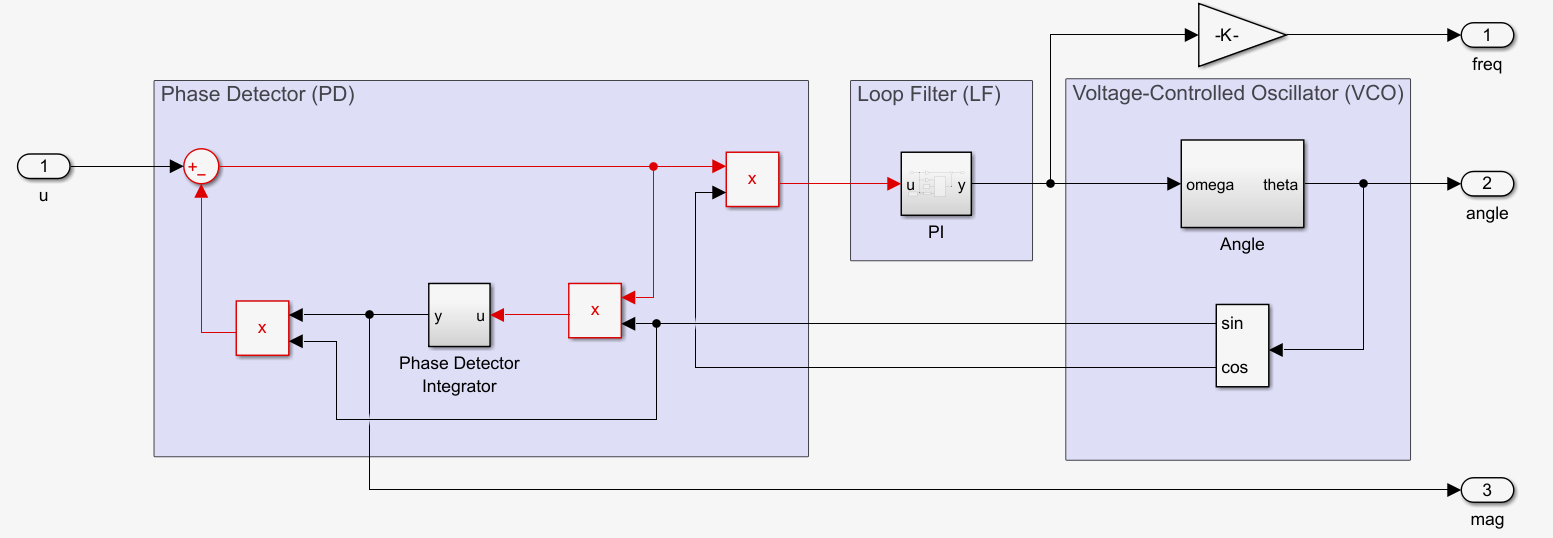

## 4. Control Algorithm

Generally, the control algorithm includes** three** parts: 

- **Charging current/voltage control**

- **Inverter and DC bus control**

- **Second-Order Generalized Integrator (SOGI).**

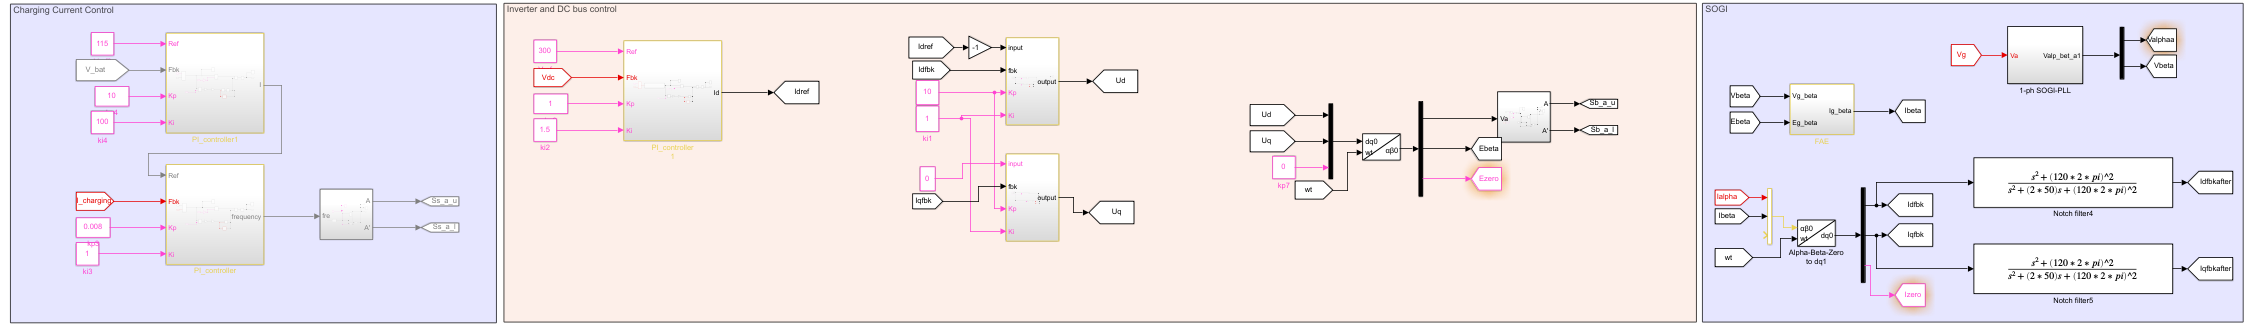

### 4.1 Charging Current and Voltage Control

The control algorithm is designed around two charging stages: constant-current charging and constant-voltage charging.

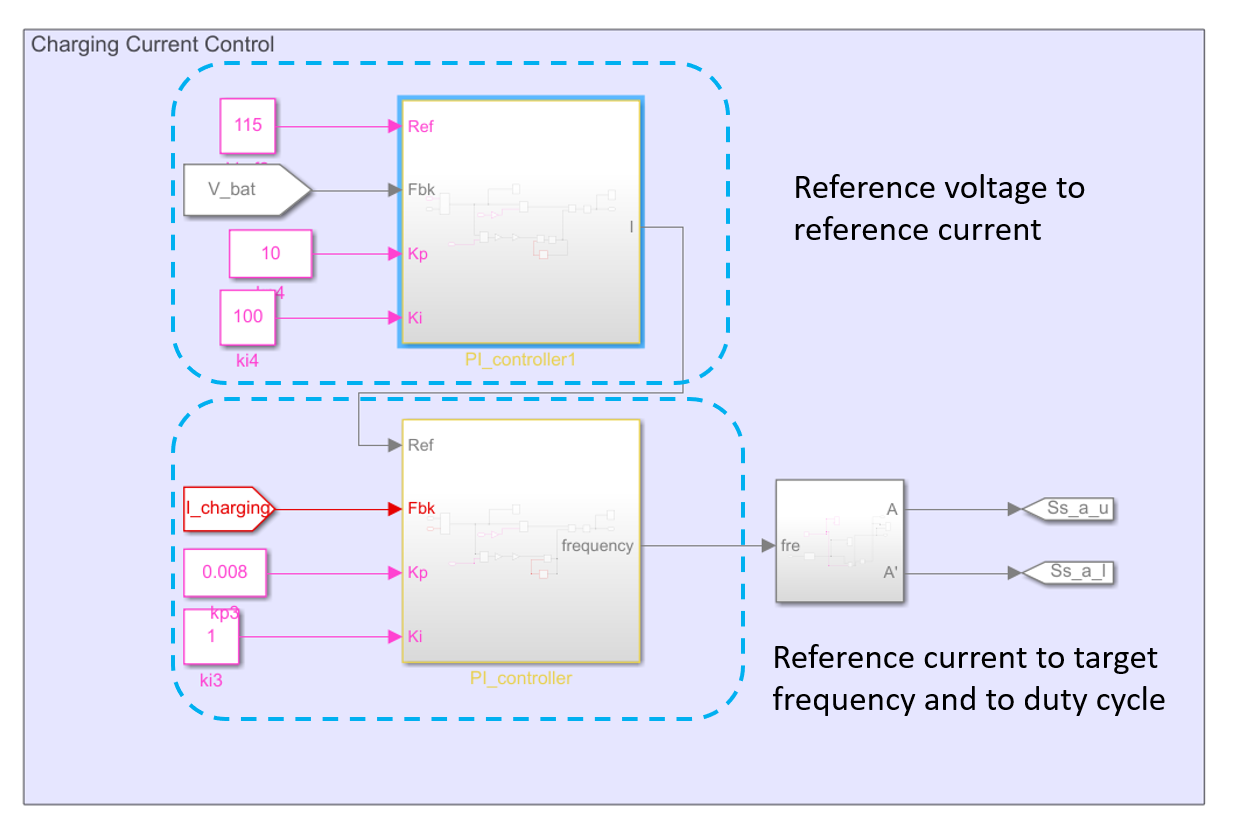

The variable `Vbat_ref` sets the target voltage for the battery charging process. Adjusting this reference affects the charging behavior of the system:

- A **higher **`Vbat_ref` increases the desired battery voltage, leading to higher charging current and output power.

- A **lower **`Vbat_ref` reduces the voltage target, resulting in slower or lighter charging behavior.

Before adjusting Vbat_ref, predict how a higher target voltage will affect charging current and battery power. Then change the target voltage with the slider, run the simulation, and compare the four responses: DC output voltage, inverter current, battery voltage and current, and battery power.

Vbat_ref=90
 
disp("Please wait for the simulation to finish. This may take a few minutes")
simOut = sim('Models/onboard_SSC_simscape.slx', 'ReturnWorkspaceOutputs', 'on');
runmodel_Vbat(simOut);
disp("Simulatin complete. You can now analyze the results")

Next, examine how the model switches between charging stages.

**Constant-current charging stage**

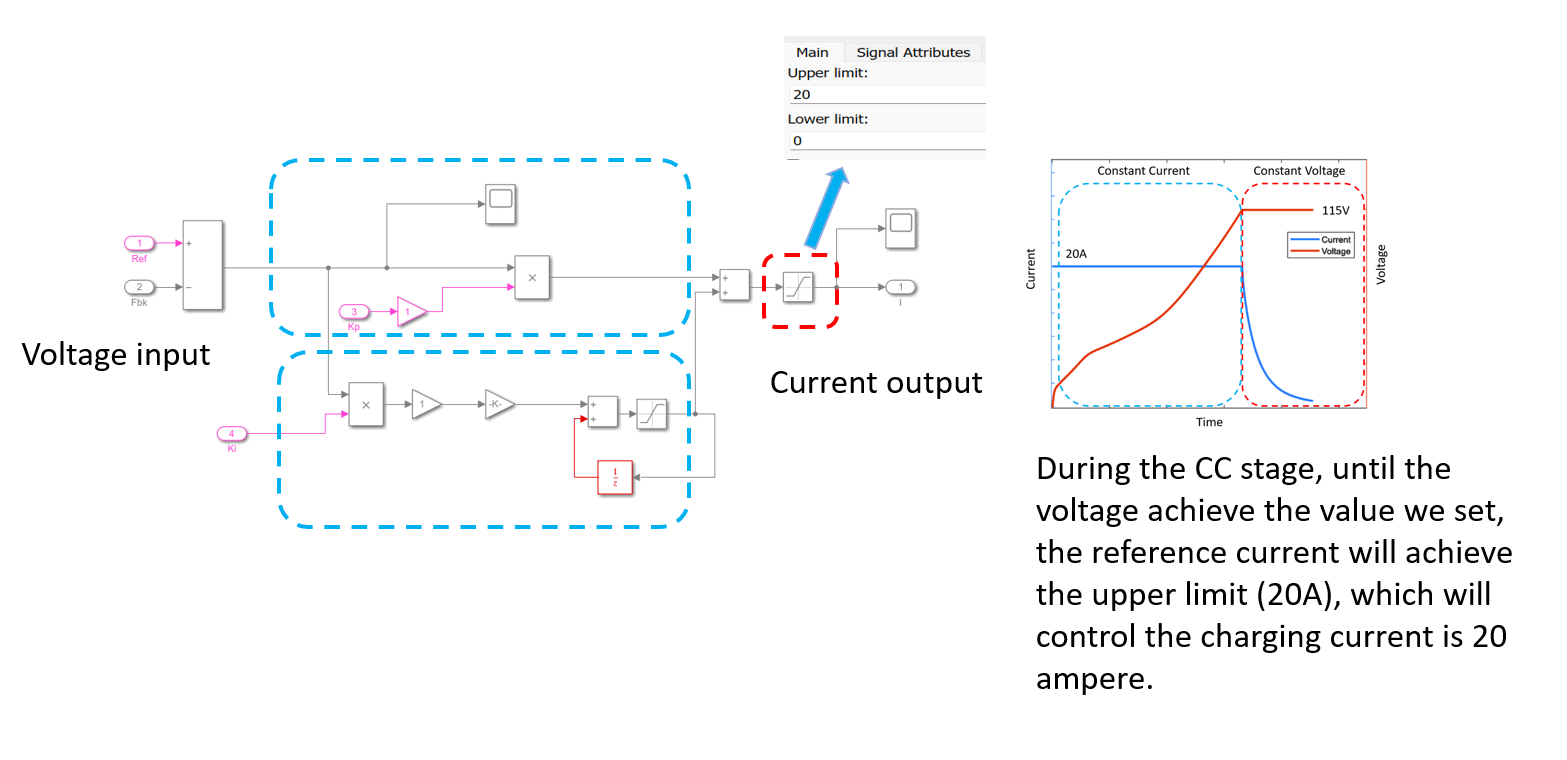

**Constant-voltage charging stage**

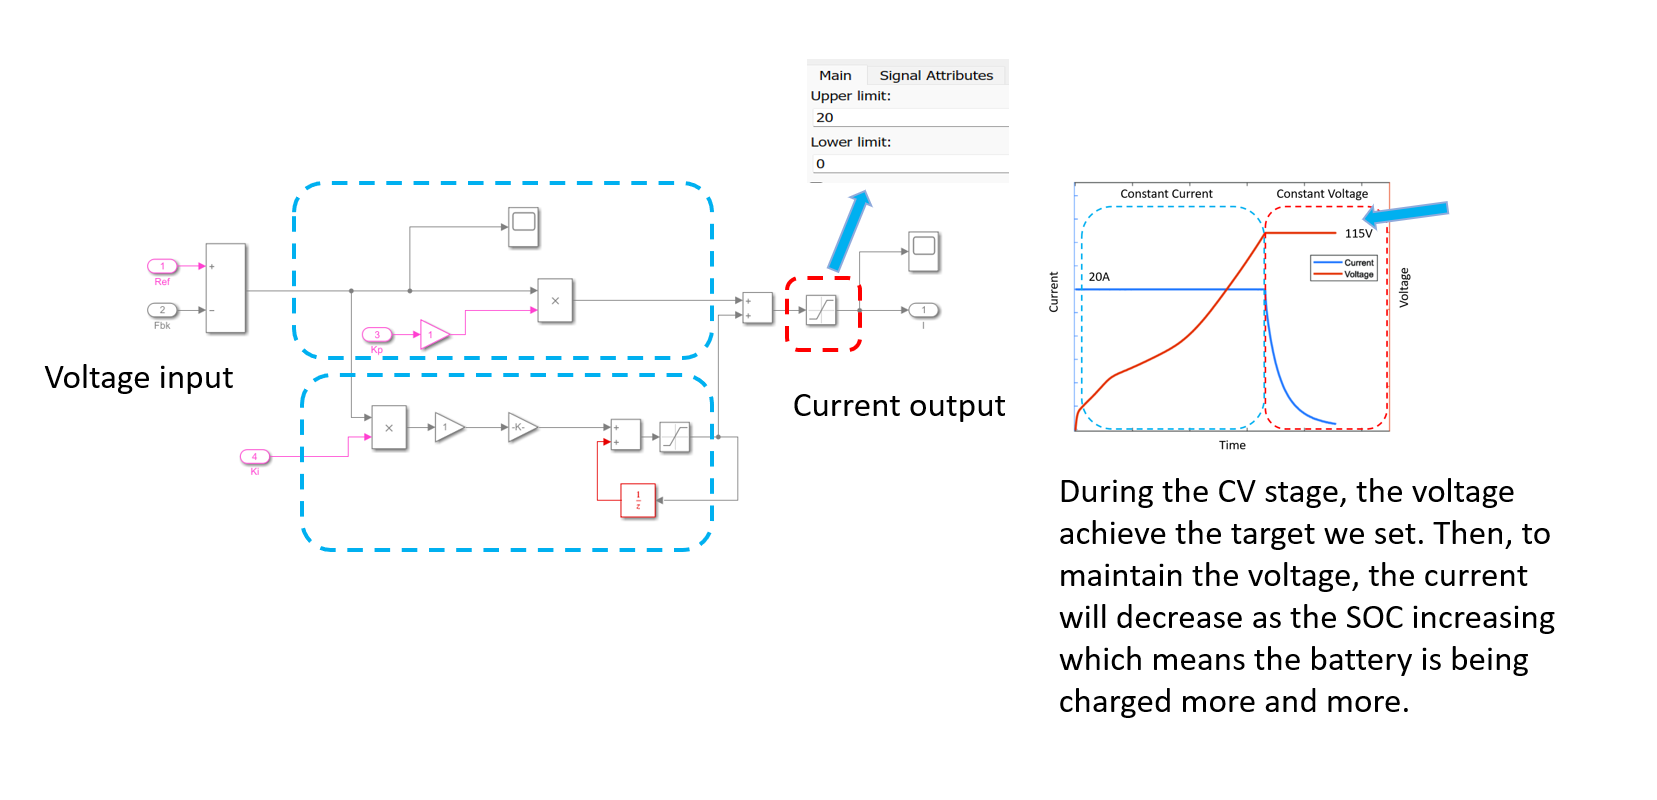

### 4.2 Inverter and DC Bus Control

The inverter control combines current control, voltage control, and duty-cycle generation.

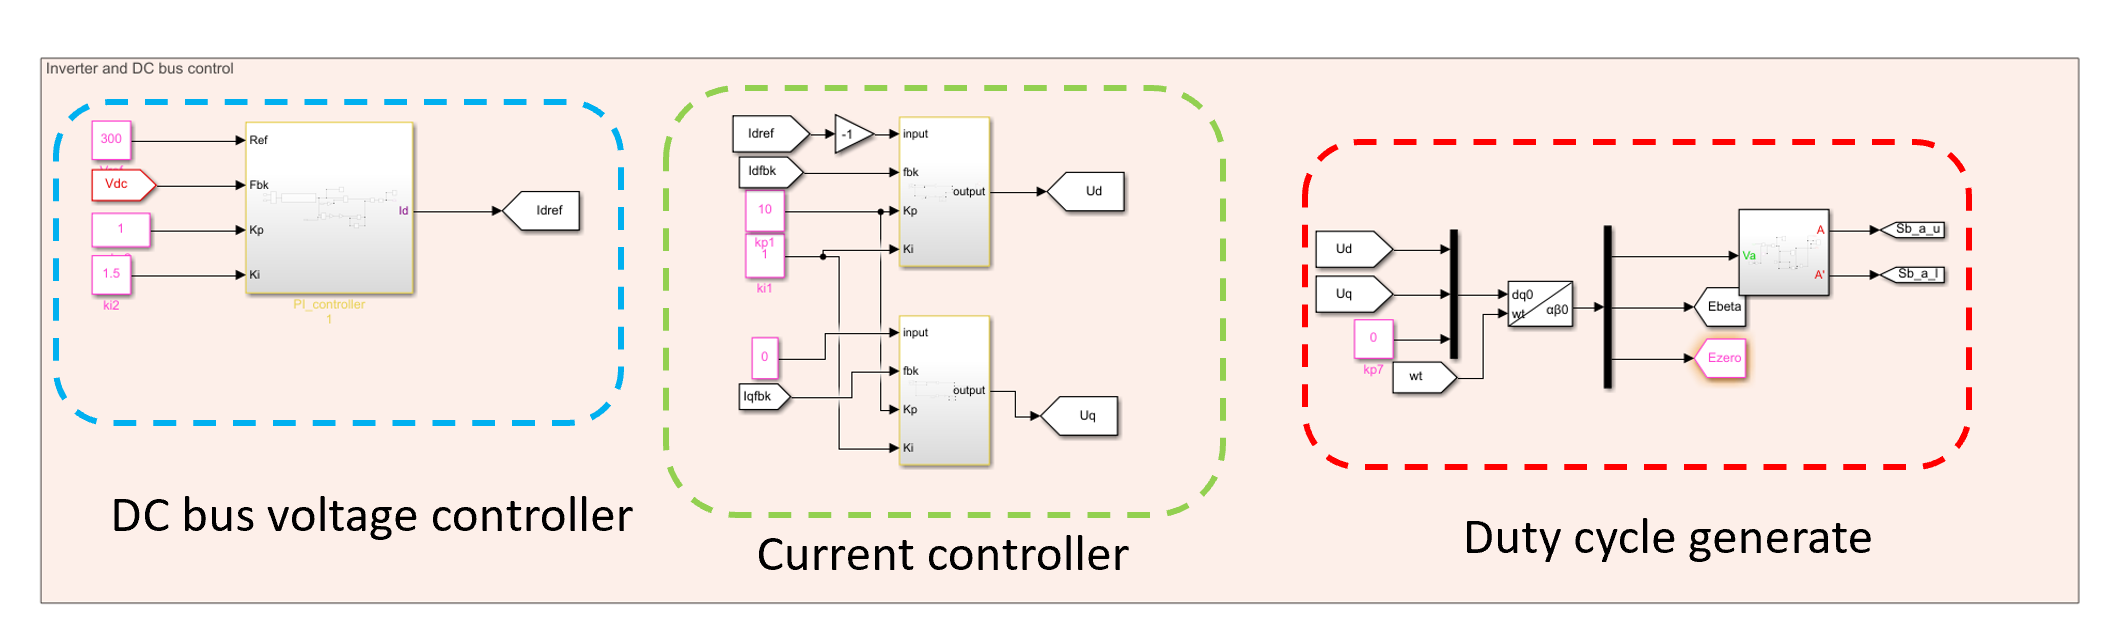

Use the drop-down menu to inspect each controller and connect it to the signals you observed in simulation.

controller("No Selection")

### 4.3 SOGI (Second-Order Generalized Integrator)

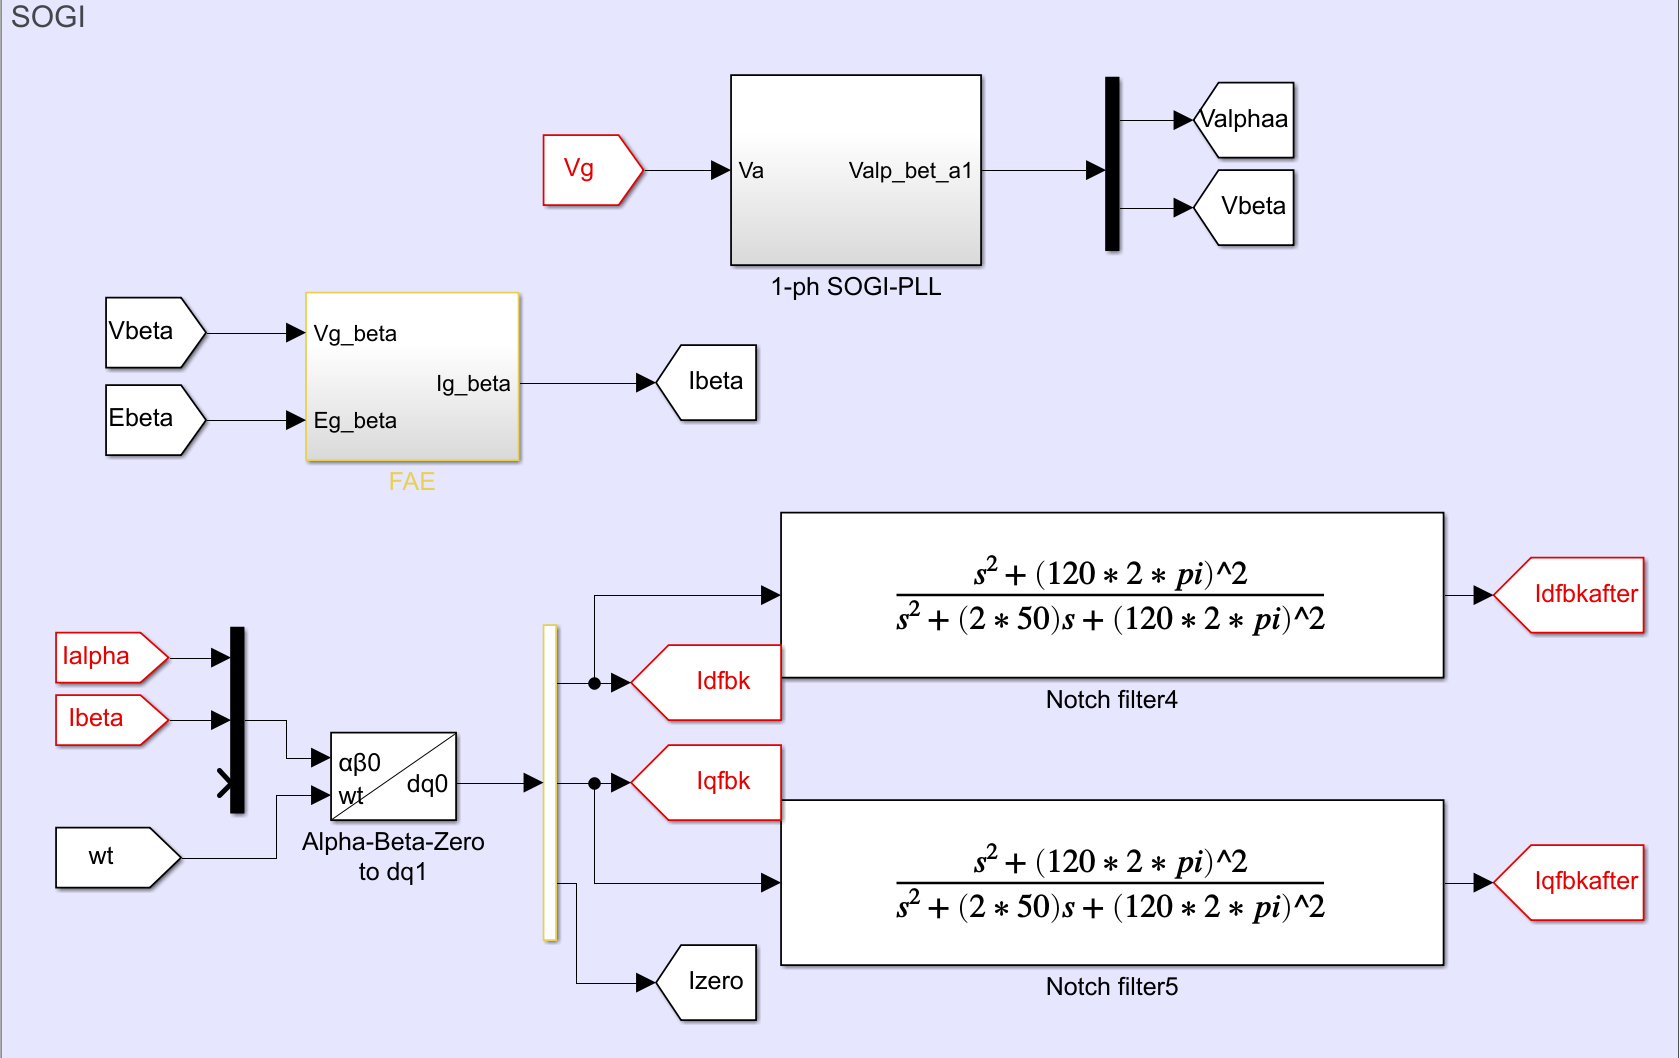

A key difference between single-phase and three-phase systems is that a single measured phase does not directly provide the orthogonal signal needed for the alpha-beta-to-dq transformation. The SOGI generates a virtual beta voltage, which is then used to calculate a virtual beta current and improve current-controller performance.

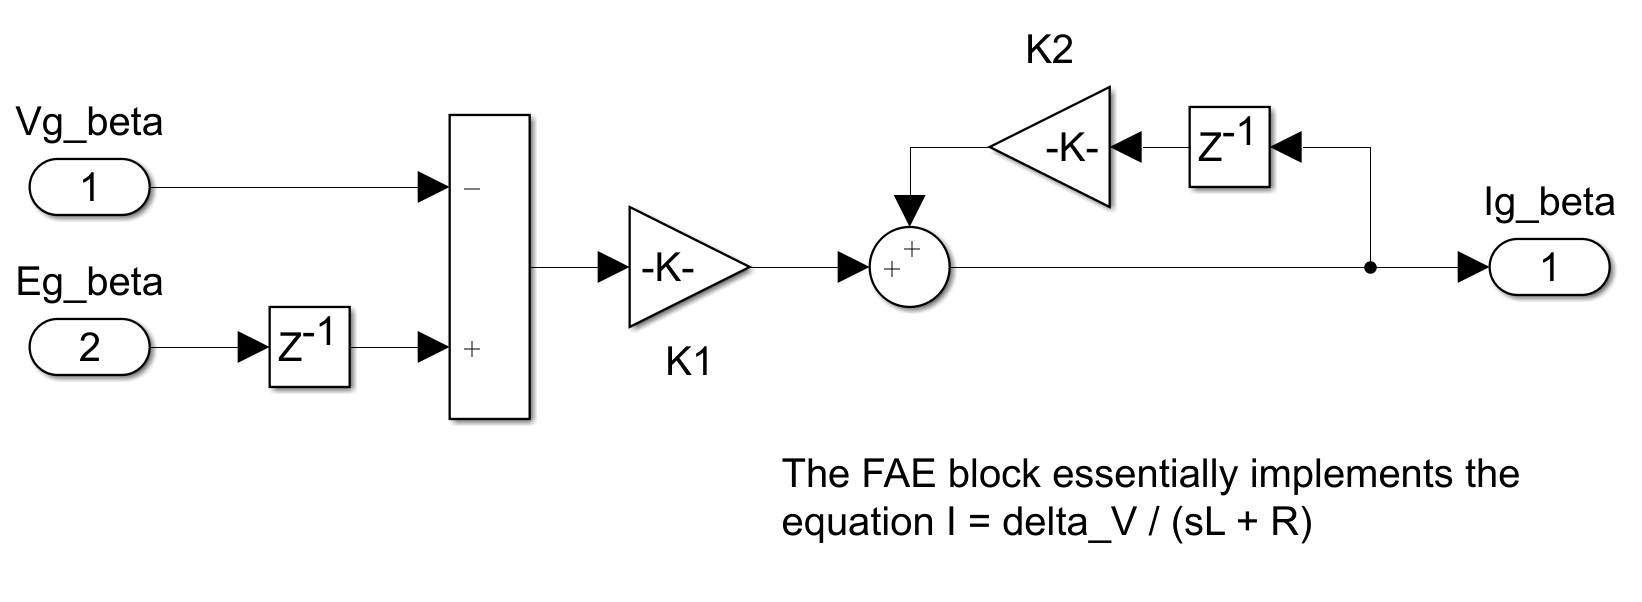

Note that Vg_beta is the voltage generated by the SOGI, and Eg_beta is the voltage calculated from the inverter. 

## 5. Analyzing the Results

Run the model in Simulink if you have not done so already. Once the simulation is complete (this may take a few minutes), use the scopes to evaluate whether the charger met its control objectives.

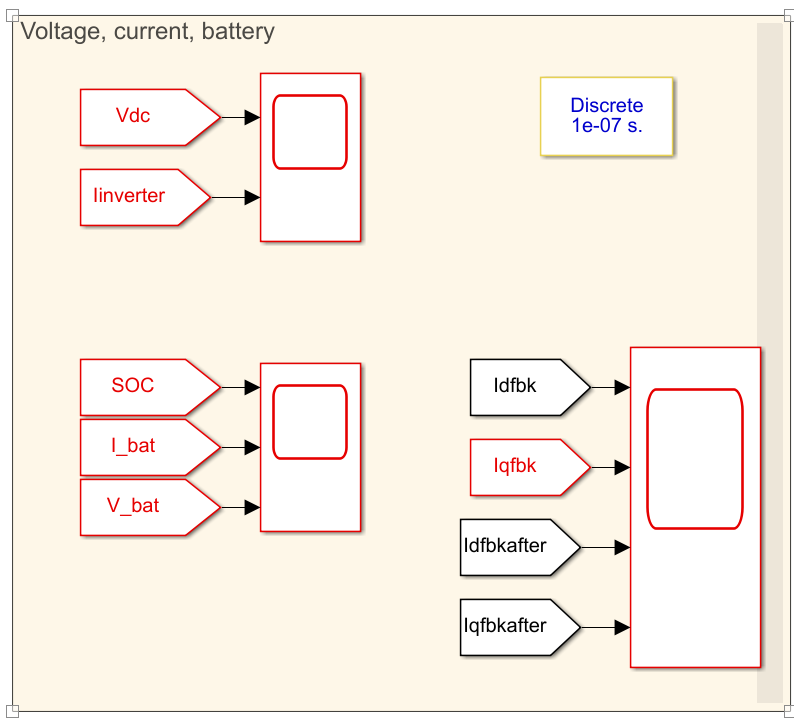

Before changing the initial SOC, predict whether the model will spend more time in constant-current charging or constant-voltage charging. Then change the initial SOC and identify where the charging mode changes.

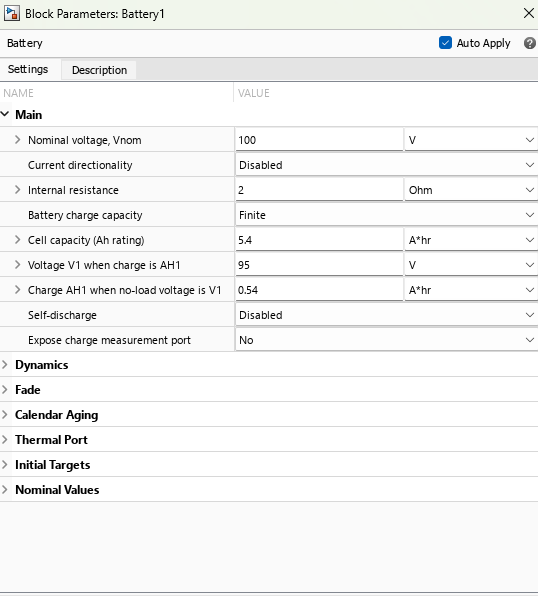

Use the menu below to compare your results with the reference simulation results.

result("No Selection")

## 6. Conclusion

This activity connected the OBC circuit, charging stages, and control structure through simulation. The key question is not only what each block does, but how the blocks work together to charge the battery safely and efficiently.

Key takeaways include:

- **System Functionality**: The OBC is responsible for converting grid AC to regulated DC to charge the EV battery safely and efficiently. It incorporates both AC-DC and DC-DC conversion stages.

- **Charging Stages**: The battery charging process consists of **constant current (CC)** and **constant voltage (CV)** phases. These are visualized clearly through the current-voltage-time plots and the `Vbat_ref` reference control.

- **Control Strategy**: A cascaded control system is implemented:

- Voltage reference is translated to charging current via outer loop.

- Current is regulated by an inner current controller.

- A **Second-Order Generalized Integrator (SOGI)** is used for reference signal synchronization and virtual β-axis current generation.

- **Simulation-Based Learning: **Adjustable parameters such as Vbat_ref and SOC let you test how voltage references and control strategies influence battery behavior, inverter current, and charging power.

- **Visualization: **The four plots (DC bus voltage, inverter current, battery voltage/current, and battery power) help you evaluate system dynamics under varying conditions.

After completing this activity, you should be able to explain how charging-stage control, inverter control, and SOGI-based synchronization support OBC operation.

## 7. Exercise

Exercise 1. What is the conversion sequence from the power grid to the battery? Additionally, ponder why each conversion stage is needed.

exerciseSol1(...
     false, ...
   false);
 

Exercise 2. What are the final control targets in the battery-control loop? Also, think of which plotted signals show whether they are achieved.

exerciseSol2(...
     false, ...
   false,...
  false);
 

Exercise 3. What is the resonant frequency of the LLC converter in the model? Reflect on where you could verify it.

exerciseSol3(...
     false, ...
   false,...
   false);
 

function switchRectifier(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "battery" "Grid" "LLC Converter" "Hbridge"])}
end
clf;
if opt == "No Selection"
else
    if opt == "battery"
        rect = imread("Images/OnBoardCharger/battery.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Grid"
        rect = imread("Images/OnBoardCharger/grid.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "LLC Converter"
        rect = imread("Images/OnBoardCharger/LLC.png");
        imshow(rect, 'Interpolation', 'bilinear');
    elseif opt == "Hbridge"
        rect = imread("Images/OnBoardCharger/Hbridge.png");
        imshow(rect, 'Interpolation', 'bilinear');
    end
end
end

function controller(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "DCbus control" "Inverter control" "SPWM"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Inverter control"
        rect = imread("Images/OnBoardCharger/controller.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "SPWM"
        rect = imread("Images/OnBoardCharger/SPWM.png");
        imshow(rect,"Interpolation","bilinear");
    elseif opt == "DCbus control"
        rect = imread("Images/OnBoardCharger/dcbus.png");
        imshow(rect,"Interpolation","bilinear");
    end
end
end

function result(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "Constant Circuit" "Constant Voltage"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Constant Circuit"
        rect = imread("Images/OnBoardCharger/Result1.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Constant Voltage"
        rect = imread("Images/OnBoardCharger/Result2.png");
        imshow(rect,"Interpolation","bilinear");
    end
end
end

function exerciseSol1(A,B)
  
    arguments
        A (1,1) logical
        B (1,1) logical
        
    end

    if ~any([A B])
        disp("Please select one that apply!")
    elseif A+B > 1
        disp("Please select only one option")
    elseif A
        disp("Correct!")
    else 
        disp("Incorrect. Please review the circuit section again")
    end
end

function exerciseSol2(A,B,C)
  
    arguments
        A (1,1) logical
        B (1,1) logical
        C (1,1) logical
        
    end

    if ~any([A B C])
        disp("Please select an answer!")
    elseif A+B+C > 1
        disp("Please select only one option")
    elseif B
        disp("Correct!")
    else 
        warning("Incorrect. Please review the control section again")
    end
end

function exerciseSol3(A,B,C)
 
    arguments
        A (1,1) logical
        B (1,1) logical
        C (1,1) logical
    end

    if ~any([A B C])
        disp("Please select an answer!")
    elseif A+B+C > 1
        disp("Please select only one option")    
    elseif C
        disp("Correct!")
    else 
        disp("Incorrect")
    end
end

function showpic1(A)

    arguments
        A (1,1) logical   
    end
    clf;
    if A
        rect = imread("Images/OnBoardCharger/CC.png");
        imshow(rect,'Interpolation',"bilinear");
    else 
    end
end
function showpic2(A)
   
    arguments
        A (1,1) logical   
    end
    clf;
    if A
        rect = imread("Images/OnBoardCharger/CV.png");
        imshow(rect,'Interpolation',"bilinear");
    else 
    end
end

function runmodel_onboard()
    warning('off', 'all'); 
    sim('Models/onboard_SSC_simscape.slx');

    try
        N = min([length(tout), length(Vdc), length(Iinverter), length(V_bat), length(I_bat)]);
        time      = tout(1:N);
        vdc_val   = Vdc(1:N);
        iinv_val  = Iinverter(1:N);
        vbat_val  = V_bat(1:N);
        ibat_val  = -I_bat(1:N);  
        power_val = vdc_val .* ibat_val;

        figure('Position', [100, 100, 1000, 800]);

 
        subplot(2,2,1);
        plot(time, vdc_val, 'b', 'LineWidth', 1.5);
        title('DC Output Voltage'); 
        xlabel('Time (s)'); ylabel('V_{dc} (V)'); grid on;

        subplot(2,2,2);
        plot(time, iinv_val, 'r', 'LineWidth', 1.5);
        title('Inverter current'); 
        xlabel('Time (s)'); ylabel('I_{inverter} (A)'); grid on;

        subplot(2,2,3);
        plot(time, vbat_val, 'm', time, ibat_val, 'g', 'LineWidth', 1.5);
        title('Battery voltage and current');
        xlabel('Time (s)'); ylabel('Value'); 
        legend('V_{bat}', 'I_{bat}'); grid on;

        subplot(2,2,4);
        plot(time, power_val, 'k', 'LineWidth', 1.5);
        title('Battery Power'); 
        xlabel('Time (s)'); ylabel('P_{out} (W)'); grid on;

    catch ME
        disp('❌ Error occurred during plotting:');
        disp(ME.message);
    end
end

function runmodel_Vbat(simOut)
    warning('off', 'all');

    try

        time      = simOut.tout;
        vdc_val   = simOut.Vdc;
        iinv_val  = simOut.Iinverter;
        vbat_val  = simOut.V_bat;
        ibat_val  = -simOut.I_bat;

     
        N = min([length(time), length(vdc_val), length(iinv_val), length(vbat_val), length(ibat_val)]);
        time      = time(1:N);
        vdc_val   = vdc_val(1:N);
        iinv_val  = iinv_val(1:N);
        vbat_val  = vbat_val(1:N);
        ibat_val  = ibat_val(1:N);
        power_val = vdc_val .* ibat_val;


        figure('Position', [100, 100, 1000, 800]);

        subplot(2,2,1);
        plot(time, vdc_val, 'b', 'LineWidth', 1.5);
        title('DC Output Voltage'); xlabel('Time (s)'); ylabel('V_{dc} (V)'); grid on;

        subplot(2,2,2);
        plot(time, iinv_val, 'r', 'LineWidth', 1.5);
        title('Inverter current'); xlabel('Time (s)'); ylabel('I_{inverter} (A)'); grid on;

        subplot(2,2,3);
        plot(time, vbat_val, 'm', time, ibat_val, 'g', 'LineWidth', 1.5);
        title('Battery voltage and current');
        xlabel('Time (s)'); ylabel('Value'); legend('V_{bat}', 'I_{bat}'); grid on;

        subplot(2,2,4);
        plot(time, power_val, 'k', 'LineWidth', 1.5);
        title('Battery Power'); xlabel('Time (s)'); ylabel('P (W)'); grid on;

    catch ME
        disp('❌ Error occurred during plotting:');
        disp(ME.message);
    end
end
